# PHASE 3 — Bilateral Hybrid Filter Sweep for ALL Noise Levels

clear; clc; close all;

addpath(genpath('./src'));

% Noise levels
noiseLevels = ["pn3", "pn5", "pn9"];

% Load clean reference slice
dataDir = "./data/raw/";
cleanFile = "t1_icbm_normal_1mm_pn0_rf0.nii";

cleanVol = load_brainweb_nifti(fullfile(dataDir, cleanFile));
slice_idx = round(size(cleanVol,3)/2);

clean_raw  = double(cleanVol(:,:,slice_idx)); % raw for filtering
clean      = mat2gray(clean_raw);             % normalized for PSNR/SSIM

fprintf("Loaded clean slice (raw + normalized).\n");

Loaded clean slice (raw + normalized).


% Bilateral parameter ranges
sigmaSpatialList   = [2, 3, 4, 5];        % spatial domain smoothing
sigmaIntensityList = [15, 20, 25, 30, 35]; % intensity smoothing
edgeThreshList     = [0.01, 0.02, 0.03, 0.04];

     SWEEPING BILATERAL FILTER FOR pn3


sp=2 | int=15 | thr=0.010 -> PSNR=32.869 SSIM=0.8533 RMSE=0.0227
sp=2 | int=15 | thr=0.020 -> PSNR=32.650 SSIM=0.8453 RMSE=0.0233
sp=2 | int=15 | thr=0.030 -> PSNR=33.329 SSIM=0.8405 RMSE=0.0216
sp=2 | int=15 | thr=0.040 -> PSNR=33.193 SSIM=0.8347 RMSE=0.0219
sp=2 | int=20 | thr=0.010 -> PSNR=32.869 SSIM=0.8533 RMSE=0.0227
sp=2 | int=20 | thr=0.020 -> PSNR=32.650 SSIM=0.8453 RMSE=0.0233
sp=2 | int=20 | thr=0.030 -> PSNR=33.329 SSIM=0.8405 RMSE=0.0216
sp=2 | int=20 | thr=0.040 -> PSNR=33.193 SSIM=0.8347 RMSE=0.0219
sp=2 | int=25 | thr=0.010 -> PSNR=32.869 SSIM=0.8533 RMSE=0.0227
sp=2 | int=25 | thr=0.020 -> PSNR=32.650 SSIM=0.8453 RMSE=0.0233
sp=2 | int=25 | thr=0.030 -> PSNR=33.329 SSIM=0.8405 RMSE=0.0216
sp=2 | int=25 | thr=0.040 -> PSNR=33.193 SSIM=0.8347 RMSE=0.0219
sp=2 | int=30 | thr=0.010 -> PSNR=32.869 SSIM=0.8533 RMSE=0.0227
sp=2 | int=30 | thr=0.020 -> PSNR=32.650 SSIM=0.8453 RMSE=0.0233
sp=2 | int=30 | thr=0.030 -> PSNR=33.329 SSIM=0.8405 RMSE=0.0216
sp=2 | int=30 | thr=0.040


----- TOP 5 PARAMETER SETS FOR pn3 -----


    sigmaSpatial    sigmaIntensity    edgeThresh     PSNR      SSIM        RMSE  
    ____________    ______________    __________    ______    _______    ________

         5                35             0.03        33.33     0.8405    0.021552
         4                35             0.03        33.33    0.84049    0.021553
         5                30             0.03        33.33    0.84049    0.021553
         4                30             0.03        33.33    0.84049    0.021554
         5                25             0.03       33.329    0.84048    0.021554




BEST PARAMETERS FOR pn3:


sigmaSpatial   = 5


sigmaIntensity = 35


edgeThresh     = 0.030


BEST PSNR      = 33.330


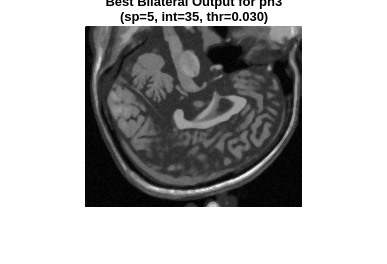

     SWEEPING BILATERAL FILTER FOR pn5


sp=2 | int=15 | thr=0.010 -> PSNR=31.563 SSIM=0.8088 RMSE=0.0264
sp=2 | int=15 | thr=0.020 -> PSNR=31.289 SSIM=0.8010 RMSE=0.0273
sp=2 | int=15 | thr=0.030 -> PSNR=30.990 SSIM=0.7911 RMSE=0.0282
sp=2 | int=15 | thr=0.040 -> PSNR=30.819 SSIM=0.7805 RMSE=0.0288
sp=2 | int=20 | thr=0.010 -> PSNR=31.563 SSIM=0.8088 RMSE=0.0264
sp=2 | int=20 | thr=0.020 -> PSNR=31.289 SSIM=0.8010 RMSE=0.0273
sp=2 | int=20 | thr=0.030 -> PSNR=30.990 SSIM=0.7911 RMSE=0.0282
sp=2 | int=20 | thr=0.040 -> PSNR=30.819 SSIM=0.7805 RMSE=0.0288
sp=2 | int=25 | thr=0.010 -> PSNR=31.563 SSIM=0.8088 RMSE=0.0264
sp=2 | int=25 | thr=0.020 -> PSNR=31.289 SSIM=0.8010 RMSE=0.0273
sp=2 | int=25 | thr=0.030 -> PSNR=30.990 SSIM=0.7911 RMSE=0.0282
sp=2 | int=25 | thr=0.040 -> PSNR=30.819 SSIM=0.7805 RMSE=0.0288
sp=2 | int=30 | thr=0.010 -> PSNR=31.563 SSIM=0.8088 RMSE=0.0264
sp=2 | int=30 | thr=0.020 -> PSNR=31.289 SSIM=0.8010 RMSE=0.0273
sp=2 | int=30 | thr=0.030 -> PSNR=30.990 SSIM=0.7911 RMSE=0.0282
sp=2 | int=30 | thr=0.040


----- TOP 5 PARAMETER SETS FOR pn5 -----


    sigmaSpatial    sigmaIntensity    edgeThresh     PSNR      SSIM        RMSE  
    ____________    ______________    __________    ______    _______    ________

         5                35             0.01       31.563    0.80878    0.026414
         5                30             0.01       31.563    0.80878    0.026414
         5                25             0.01       31.563    0.80878    0.026414
         4                35             0.01       31.563    0.80878    0.026414
         5                20             0.01       31.563    0.80878    0.026414




BEST PARAMETERS FOR pn5:


sigmaSpatial   = 5


sigmaIntensity = 35


edgeThresh     = 0.010


BEST PSNR      = 31.563


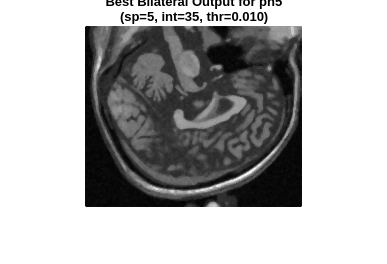

     SWEEPING BILATERAL FILTER FOR pn9


sp=2 | int=15 | thr=0.010 -> PSNR=28.193 SSIM=0.7354 RMSE=0.0389
sp=2 | int=15 | thr=0.020 -> PSNR=27.376 SSIM=0.7286 RMSE=0.0428
sp=2 | int=15 | thr=0.030 -> PSNR=27.170 SSIM=0.7185 RMSE=0.0438
sp=2 | int=15 | thr=0.040 -> PSNR=26.983 SSIM=0.7066 RMSE=0.0448
sp=2 | int=20 | thr=0.010 -> PSNR=28.193 SSIM=0.7354 RMSE=0.0389
sp=2 | int=20 | thr=0.020 -> PSNR=27.376 SSIM=0.7286 RMSE=0.0428
sp=2 | int=20 | thr=0.030 -> PSNR=27.170 SSIM=0.7185 RMSE=0.0438
sp=2 | int=20 | thr=0.040 -> PSNR=26.983 SSIM=0.7066 RMSE=0.0448
sp=2 | int=25 | thr=0.010 -> PSNR=28.193 SSIM=0.7354 RMSE=0.0389
sp=2 | int=25 | thr=0.020 -> PSNR=27.376 SSIM=0.7286 RMSE=0.0428
sp=2 | int=25 | thr=0.030 -> PSNR=27.170 SSIM=0.7185 RMSE=0.0438
sp=2 | int=25 | thr=0.040 -> PSNR=26.983 SSIM=0.7066 RMSE=0.0448
sp=2 | int=30 | thr=0.010 -> PSNR=28.193 SSIM=0.7354 RMSE=0.0389
sp=2 | int=30 | thr=0.020 -> PSNR=27.376 SSIM=0.7286 RMSE=0.0428
sp=2 | int=30 | thr=0.030 -> PSNR=27.170 SSIM=0.7185 RMSE=0.0438
sp=2 | int=30 | thr=0.040


----- TOP 5 PARAMETER SETS FOR pn9 -----


    sigmaSpatial    sigmaIntensity    edgeThresh     PSNR      SSIM       RMSE  
    ____________    ______________    __________    ______    ______    ________

         2                15             0.01       28.193    0.7354    0.038936
         3                15             0.01       28.193    0.7354    0.038936
         4                15             0.01       28.193    0.7354    0.038936
         5                15             0.01       28.193    0.7354    0.038936
         2                20             0.01       28.193    0.7354    0.038936




BEST PARAMETERS FOR pn9:


sigmaSpatial   = 2


sigmaIntensity = 15


edgeThresh     = 0.010


BEST PSNR      = 28.193


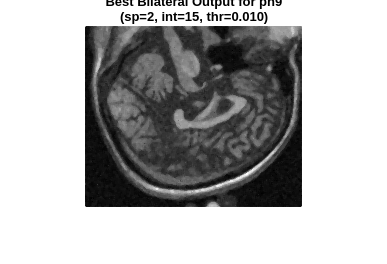

% MAIN LOOP OVER NOISE LEVELS
for nl = noiseLevels

    fprintf("\n=====================================\n");
    fprintf("     SWEEPING BILATERAL FILTER FOR %s\n", nl);
    fprintf("=====================================\n");

    noisyFile = "t1_icbm_normal_1mm_" + nl + "_rf0.nii";
    noisyVol  = load_brainweb_nifti(fullfile(dataDir, noisyFile));

    noisy_raw = double(noisyVol(:,:,slice_idx));
    noisy     = mat2gray(noisy_raw);   % for visualization only

    best_psnr = -inf;
    best_img_norm = [];
    best_params = [];

    idx = 1;
    results = struct();

    % PARAMETER SWEEP
    for sigmaSpatial = sigmaSpatialList
        for sigmaIntensity = sigmaIntensityList
            for edgeThresh = edgeThreshList

                % Run bilateral hybrid filter on RAW image
                out_raw = bilateral_hybrid_filter( ...
                            noisy_raw, ...
                            sigmaSpatial, ...
                            sigmaIntensity, ...
                            edgeThresh );

                % Normalize output for metrics
                out = mat2gray(out_raw);

                % Compute metrics
                P = psnr(out, clean);
                S = ssim(out, clean);
                R = sqrt(immse(out, clean));

                % Store results
                results(idx).sigmaSpatial   = sigmaSpatial;
                results(idx).sigmaIntensity = sigmaIntensity;
                results(idx).edgeThresh     = edgeThresh;
                results(idx).PSNR           = P;
                results(idx).SSIM           = S;
                results(idx).RMSE           = R;

                fprintf("sp=%d | int=%d | thr=%.3f -> PSNR=%.3f SSIM=%.4f RMSE=%.4f\n", ...
                        sigmaSpatial, sigmaIntensity, edgeThresh, P, S, R);

                % Track best PSNR
                if P > best_psnr
                    best_psnr = P;
                    best_img_norm = out;
                    best_params = [sigmaSpatial, sigmaIntensity, edgeThresh];
                end

                idx = idx + 1;
            end
        end
    end

    % SORT RESULTS
    T = struct2table(results);
    T_sorted = sortrows(T, {'PSNR','SSIM','RMSE'}, {'descend','descend','ascend'});

    fprintf("\n----- TOP 5 PARAMETER SETS FOR %s -----\n", nl);
    disp(T_sorted(1:5,:));

    % PRINT BEST PARAMS
    fprintf("\nBEST PARAMETERS FOR %s:\n", nl);
    fprintf("sigmaSpatial   = %d\n", best_params(1));
    fprintf("sigmaIntensity = %d\n", best_params(2));
    fprintf("edgeThresh     = %.3f\n", best_params(3));
    fprintf("BEST PSNR      = %.3f\n", best_psnr);

    %% SHOW BEST OUTPUT
    figure('Position',[300 200 600 600]);
    imshow(best_img_norm, []);
    title(sprintf("Best Bilateral Output for %s\n(sp=%d, int=%d, thr=%.3f)", ...
        nl, best_params(1), best_params(2), best_params(3)));

end